## Pendulum Swing-up Model

The reinforcement learning environment for this example is a simple frictionless pendulum that is initially hanging in a downward position. The training goal is to make the pendulum stand upright without falling over using minimal control effort. 

Open the model.

mdl = 'Rehabilitation_Device_R2017a';
open_system(mdl)
max_tau=2;
I=0;
c=0;
g=9.81;
l=1;
m=1;
theta0=0;
theta_dot0=0;

For this model:

- The upward balanced pendulum position is `0` radians, and the downward hanging position is `pi` radians.

- The torque action signal from the agent to the environment is from `-2` to `2` Nm.

- The observations from the environment are the sine of the pendulum angle, the cosine of the pendulum angle, and the pendulum angle derivative.

- The reward $r_t$, provided at every time step, is:


$$r_t =-\left({\theta_t }^2 +0\ldotp 1{\dot{\theta_t } }^2 +0\ldotp 001u_{t-1}^2 \right)$$


where:

- $\theta_t$ is the angle of displacement from the upright position

- $\dot{\theta_t }$ is the derivative of the displacement angle

- $u_{t-1}$ is the control effort from the previous time step.

For more information on this model, see [Simple Pendulum Balancing Model](docid:rl_ug#mw_9372e520-2760-4363-a7ea-983478559539).

## Create Environment Interface

Create a predefined environment interface for the pendulum.

actionInfo = rlNumericSpec([1 1]);
actionInfo.LowerLimit=-2;
actionInfo.UpperLimit=2;
actionInfo.Name = 'torque';

observationInfo = rlNumericSpec([3 1]);
observationInfo.Name = 'observations';
observationInfo.Description = 'sin,cos , and dtheta';

env = rlSimulinkEnv(mdl,[mdl '/RL Agent'],observationInfo,actionInfo)

env =   SimulinkEnvWithAgent with properties:

             Model: "Rehabilitation_Device_R2017a"
        AgentBlock: "Rehabilitation_Device_R2017a/RL Agent"
          ResetFcn: []
    UseFastRestart: 'on'


The interface has a continuous action space where the agent can apply possible torque values from `-2` to `2` Nm to the pendulum.

Set the observations of the environment to be the sine of the pendulum angle, the cosine of the pendulum angle, and the pendulum angle derivative.

numObs = 3;
set_param('Rehabilitation_Device_R2017a/create observations','ThetaObservationHandling','sincos');

To define the initial condition of the pendulum as hanging downward, specify an environment reset function using an anonymous function handle. This reset function sets the model workspace variable `theta0` to `pi`.

env.ResetFcn = @(in)setVariable(in,'theta0',pi,'Workspace',mdl);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds

Ts = 0.05;
Tf = 20;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG agent

A DDPG agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and one output. For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(300,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([1 1 1],'Normalization','none','Name','action')
    fullyConnectedLayer(300,'Name','CriticActionFC1','BiasLearnRateFactor',0)];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

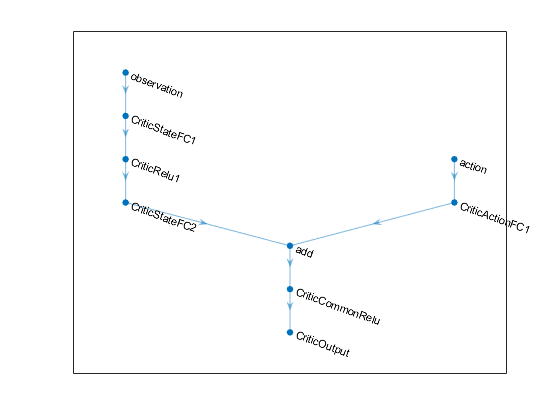

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',1e-03,'GradientThreshold',1);

Create the critic representation using the specified deep neural network and options. You must also specify the action and observation info for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'action'},criticOpts);

A DDPG agent decides which action to take given observations using an actor representation. To create the actor, first create a deep neural network with one input, the observation, and one output, the action.

Construct the actor similarly to the critic. For more information, see [`rlDeterministicActorRepresentation`](docid:rl_ref#mw_425a8728-2966-45c4-9d2a-488aa4a506bf).

actorNetwork = [
    imageInputLayer([numObs 1 1],'Normalization','none','Name','observation')
    fullyConnectedLayer(400,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(300,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(1,'Name','ActorFC3')
    tanhLayer('Name','ActorTanh')
    scalingLayer('Name','ActorScaling','Scale',max(actInfo.UpperLimit))];

actorOpts = rlRepresentationOptions('LearnRate',1e-04,'GradientThreshold',1);

actor = rlDeterministicActorRepresentation(actorNetwork,obsInfo,actInfo,'Observation',{'observation'},'Action',{'ActorScaling'},actorOpts);

To create the DDPG agent, first specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

agentOpts = rlDDPGAgentOptions(...
    'SampleTime',Ts,...
    'TargetSmoothFactor',1e-3,...
    'ExperienceBufferLength',1e6,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',128);
agentOpts.NoiseOptions.Variance = 0.6;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;

Then, create the DDPG agent using the specified actor representation, critic representation and agent options. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run training for at most `50000` episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `-740` over five consecutive episodes. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than `-740`.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'ScoreAveragingWindowLength',5,...
    'Verbose',false,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',-740,...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',-740);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

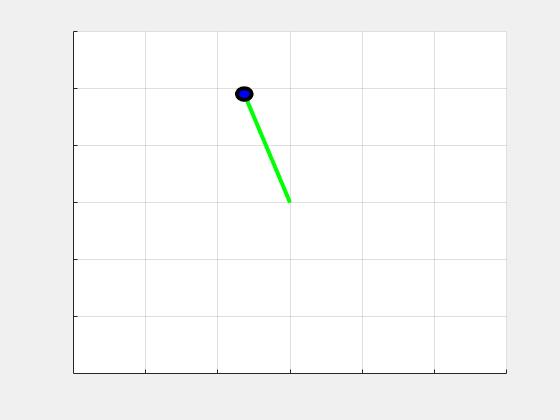

doTraining = true;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('agent1.mat','agent')
end

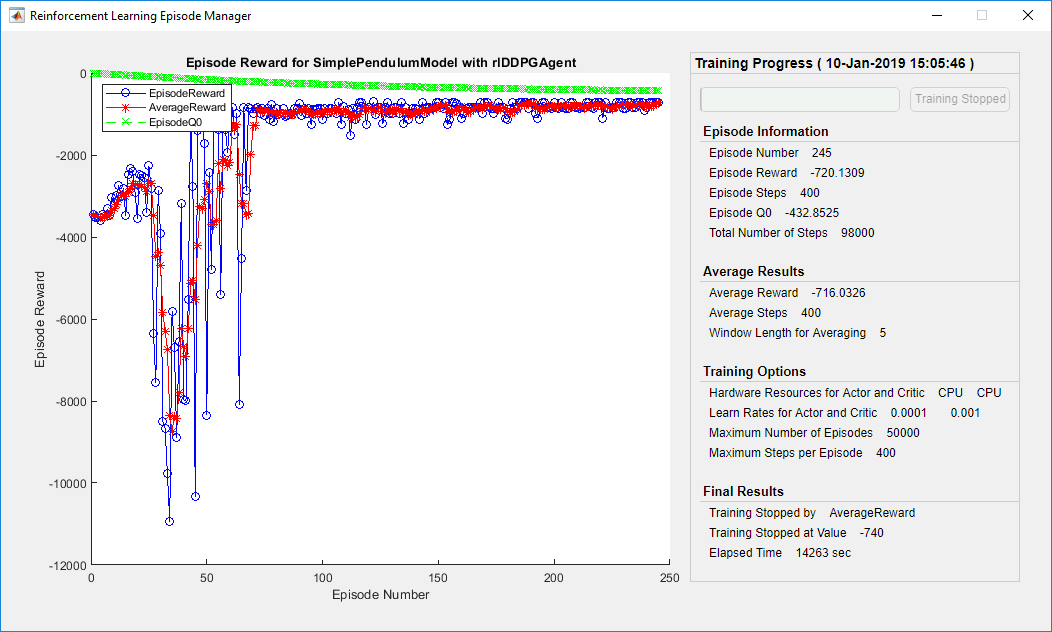

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate it within the pendulum environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

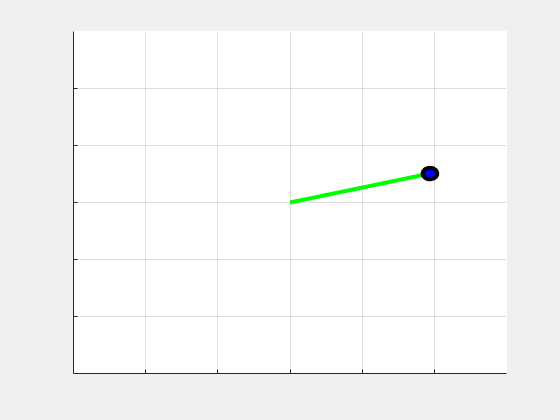

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

*Copyright 2019 The MathWorks, Inc.*